clc;
close all;
clear variables;

### Simulacija

Parametri simulacije

sim_file_name = "buck_boost_DCDC_sim";
open_system(sim_file_name);

sim_duration = 1; % sec
time_step = 1e-4;

Propusni opseg

w0 = 150; % rad/s
w_diff = w0 * 20; % da bude dovoljno van propusnog opsega
w_prefiltar = 0.667 * w0; % odokativno

Feedback linearizacija

p = 3*w0; %trostruki pol da bi prop opseg bio w0

k_i = p^3;
k_0 = 3*p^2;
k_1 = 3*p;
K_fl = [k_i,k_0,k_1];

subsystem_name = "/Feedback linearizacija";

feedback_linearizacija_foo(sim_file_name, subsystem_name)

Sliding mode control

beta = 10000;
p = 2*w0;
K_0 = 2*p;
K_i = p^2;
K_smc = [K_i, K_0];

K_smc_0 = [0, K_smc];

subsystem_name = "/Klizno upravljanje";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)


Boundry layer sliding mode control

phi = beta / 20 / p;
subsystem_name = "/Klizno upravljanje sa granicnim slojem";
sliding_mode_control_foo(sim_file_name, subsystem_name, K_smc)

Parametri sistema

[L, R, C, E, x_2e] = nominalni_parametri();

Referenca i poremecaj

t_ref = [1/6, 2/6, 3/6, 4/6 ] * sim_duration;
step_ref = [0.5, -0.5, -0.5, 0.5] * x_2e;

t_poremecaj = [5/6] * sim_duration;
step_poremecaj = [1/3] * E;

Opsti parametri kontrolera

R_dot_enable = 1;
prefiltar_enable = 1;

% "smc", "fbl", "bl smc"
ime_kontrolera = "fbl";

Simulacija

out = sim(sim_file_name);

### Crtanje

main_plot_linewidth = 1;
auxiliary_plot_linewidth = 0.5;

#### Upravljanje

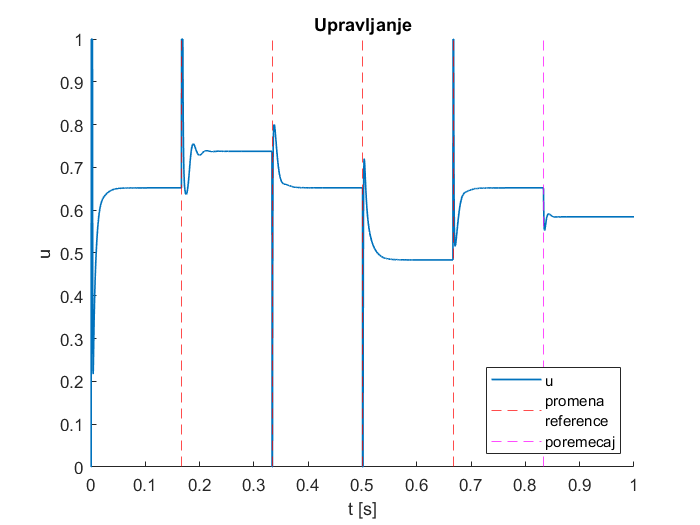

y_oznaka = "u";
naslov = "Upravljanje";
target_timeseries = out.upravljanje;
ref_flg = true;
poremecaj_flg = true;

fig = crtanje_celog_signala(naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);

Prelazak ka nominalnom rezimu rada

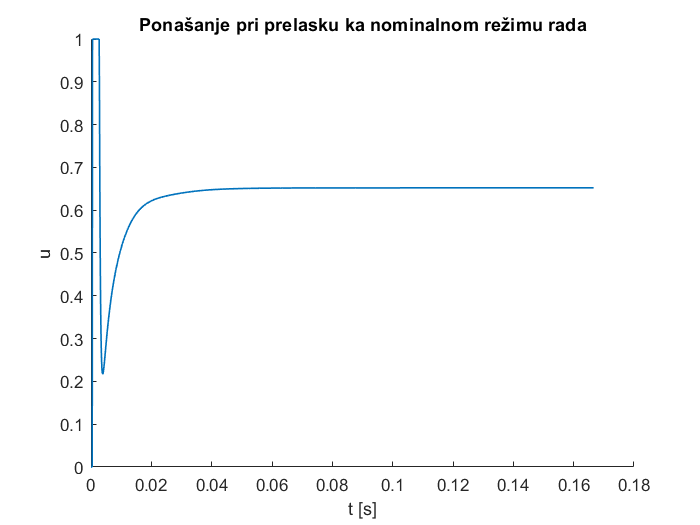

naslov = "Ponašanje pri prelasku ka nominalnom režimu rada";
t_start = 0;
t_end = t_ref(1);

fig = crtanje_segmenta_vremena(naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

Odziv na referencu

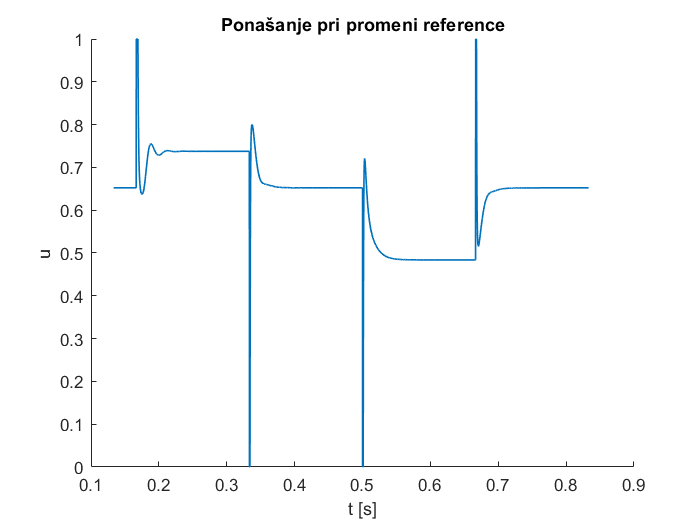

naslov = "Ponašanje pri promeni reference";
t_start = 0.8*t_ref(1);
t_end = t_poremecaj(1);

fig = crtanje_segmenta_vremena(naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

Poremecaj

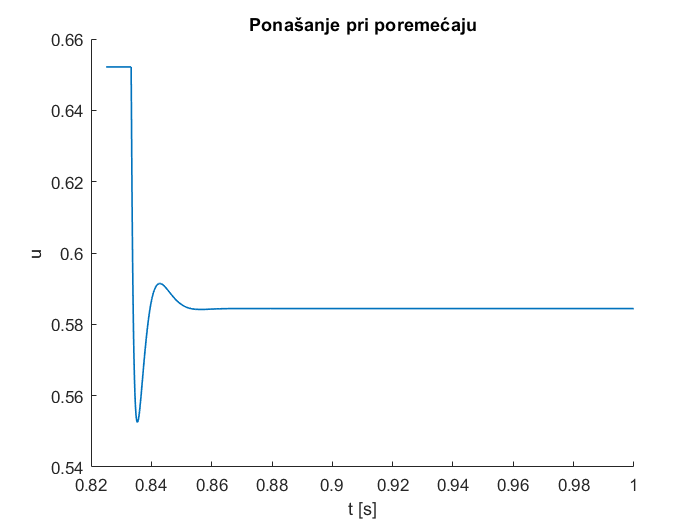

naslov = "Ponašanje pri poremećaju";
t_start = 0.99 * t_poremecaj(1);
t_end = sim_duration;

fig = crtanje_segmenta_vremena(naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

#### Izlaz

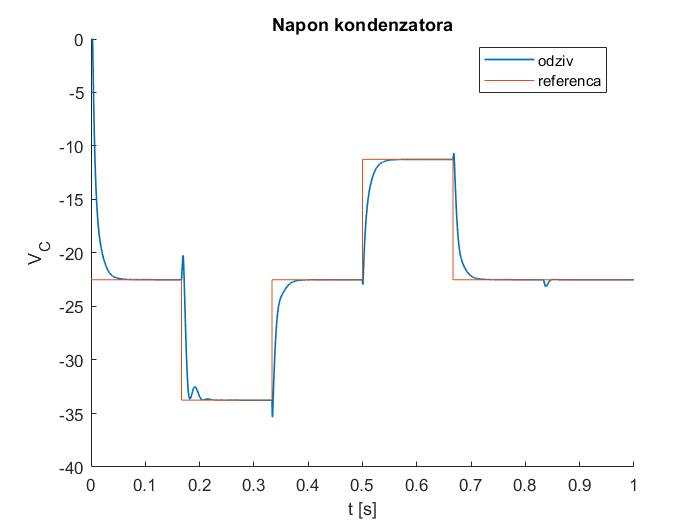

y_oznaka = "V_C";
naslov = "Napon kondenzatora";
target_timeseries = out.x2;
ref_flg = false;
poremecaj_flg = false;

fig = crtanje_celog_signala(naslov, y_oznaka, target_timeseries, t_ref, t_poremecaj, main_plot_linewidth, auxiliary_plot_linewidth, ref_flg, poremecaj_flg);
fig = crtanje_reference(fig, out, 0, sim_duration);

Prelazak ka nominalnom rezimu rada

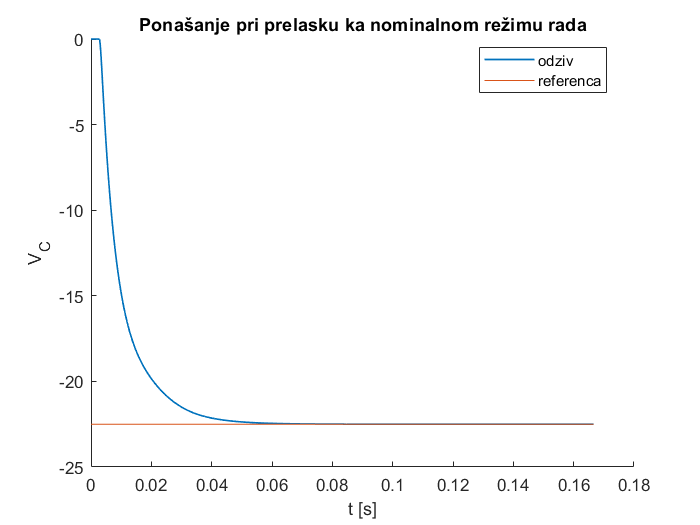

naslov = "Ponašanje pri prelasku ka nominalnom režimu rada";
t_start = 0;
t_end = t_ref(1);

fig = crtanje_segmenta_vremena(naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);

fig = crtanje_reference(fig, out, t_start, t_end);

Odziv na referencu

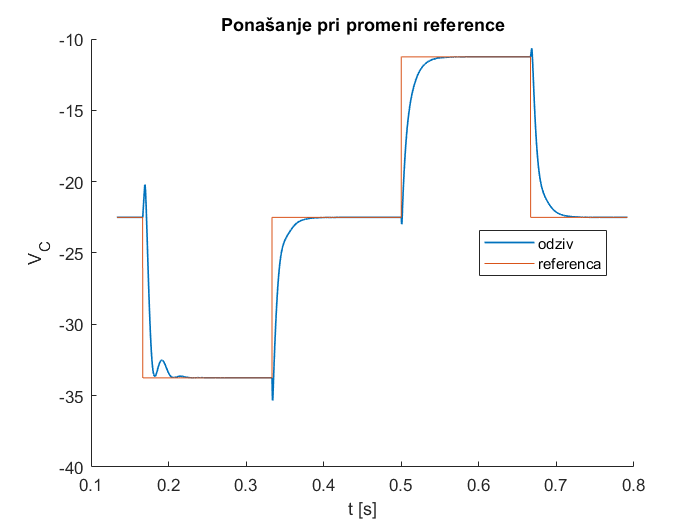

naslov = "Ponašanje pri promeni reference";
t_start = 0.8*t_ref(1);
t_end = 0.95*t_poremecaj(1);

fig = crtanje_segmenta_vremena(naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);
fig = crtanje_reference(fig, out, t_start, t_end);

Poremecaj

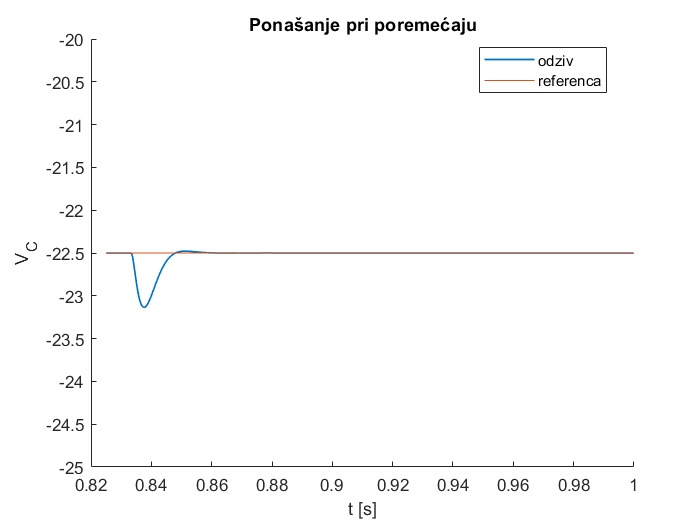

naslov = "Ponašanje pri poremećaju";
t_start = 0.99 * t_poremecaj(1);
t_end = sim_duration;

fig = crtanje_segmenta_vremena(naslov, y_oznaka, out, target_timeseries, t_start, t_end, main_plot_linewidth);
fig = crtanje_reference(fig, out, t_start, t_end);
ylim([-25, -20])

#### Fazni portret

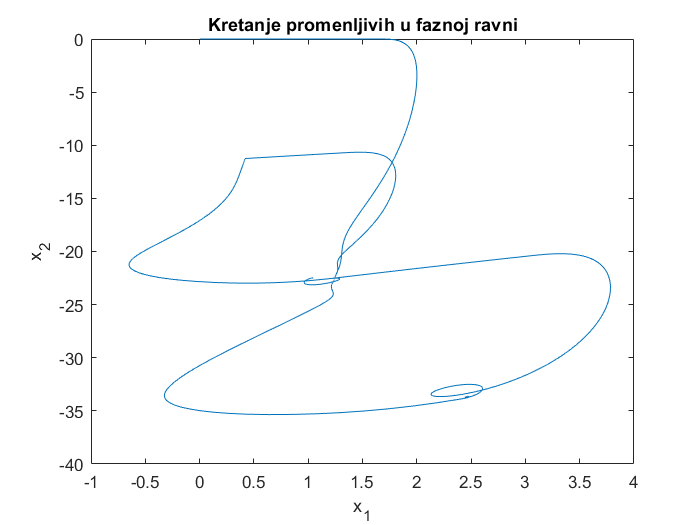

fig = figure();
plot(out.x1.Data, out.x2.Data)
title("Kretanje promenljivih u faznoj ravni")
xlabel("x_1")
ylabel("x_2")